clearvars
close all
clc
load("FA_973_R_2.mat");
lat = Position.latitude;
lon = Position.longitude;

load("Fermate_973.mat");
lat_true = stops_lat_rit;
lon_true = stops_long_rit;

speed = Position.speed;

basemapName = "offlineBusMap";
mbtilesFile = "osm-2020-02-10-v3.11_italy_milan.mbtiles";

addCustomBasemap(basemapName, mbtilesFile)

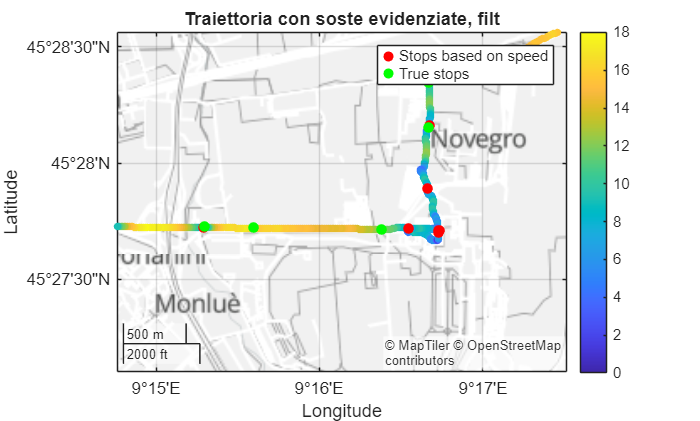

N = 5;
b = ones(1, N) / N;
a = 1;
speed_f = filtfilt(b, a, speed); %media mobile senza introduzione di ritardo

isStopped = speed_f < 1.0;
figure;
geobasemap offlineBusMap

geoscatter(lat(~isStopped), lon(~isStopped), 20, speed(~isStopped), 'filled')
hold on
s = geoscatter(lat(isStopped), lon(isStopped), 40, 'red', 'filled');
t = geoscatter(lat_true, lon_true, 40, 'green', 'filled');

colorbar
title('Traiettoria con soste evidenziate, filt')
legend([s, t], {'Stops based on speed', 'True stops'});

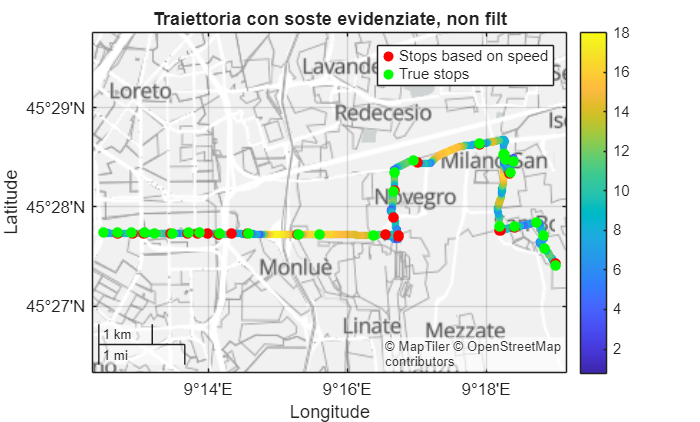

speed_f = speed;
isStopped = speed_f < 0.7; %Confrontando i risultati la terrei non filtrata che non cambia e non perdiamo detagli

figure;
geobasemap offlineBusMap

geoscatter(lat(~isStopped), lon(~isStopped), 20, speed(~isStopped), 'filled')
hold on
s = geoscatter(lat(isStopped), lon(isStopped), 40, 'red', 'filled');
t = geoscatter(lat_true, lon_true, 40, 'green', 'filled');

colorbar
title('Traiettoria con soste evidenziate, non filt')
legend([s, t], {'Stops based on speed', 'True stops'});

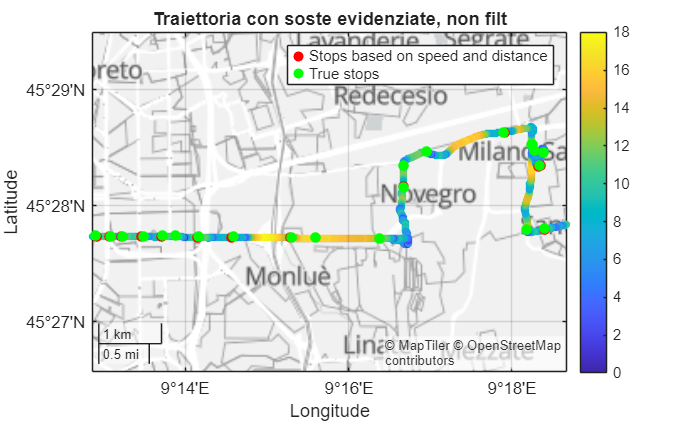

%Implementaato lo stesso metodo usato in data elaboration, per verificare anche graficamente il funzionametno (un log alla volta);
[Lat_And, Stops_Lat_And] = ndgrid(lat, lat_true);
[Lon_And, Stops_Lon_And] = ndgrid(lon, lon_true);
isStopped = deg2km(distance(Lat_And, Lon_And, Stops_Lat_And, Stops_Lon_And))*1000 < 35;
isStopped = any(isStopped, 2);
isStopped  = isStopped & (speed<0.7);
figure;
geobasemap offlineBusMap

geoscatter(lat(~isStopped), lon(~isStopped), 20, speed(~isStopped), 'filled')
hold on
s = geoscatter(lat(isStopped), lon(isStopped), 40, 'red', 'filled');
t = geoscatter(lat_true, lon_true, 40, 'green', 'filled');

colorbar
title('Traiettoria con soste evidenziate, non filt')
legend([s, t], {'Stops based on speed and distance', 'True stops'});